% ExpValues_AKLT

% preparation of AKLT from given script


clear

AKLT = zeros(2,2,3);
% local spin S_z = +1
AKLT(1,2,1) = sqrt(2/3);
% local spin S_z = 0
AKLT(1,1,2) = -1/sqrt(3);
AKLT(2,2,2) = +1/sqrt(3);
% local spin S_z = -1
AKLT(2,1,3) = -sqrt(2/3);


[S,I] = getLocalSpace('Spin',1);
Sz = S(:,:,2); % spin-z


Norm of MPS = 0.7071


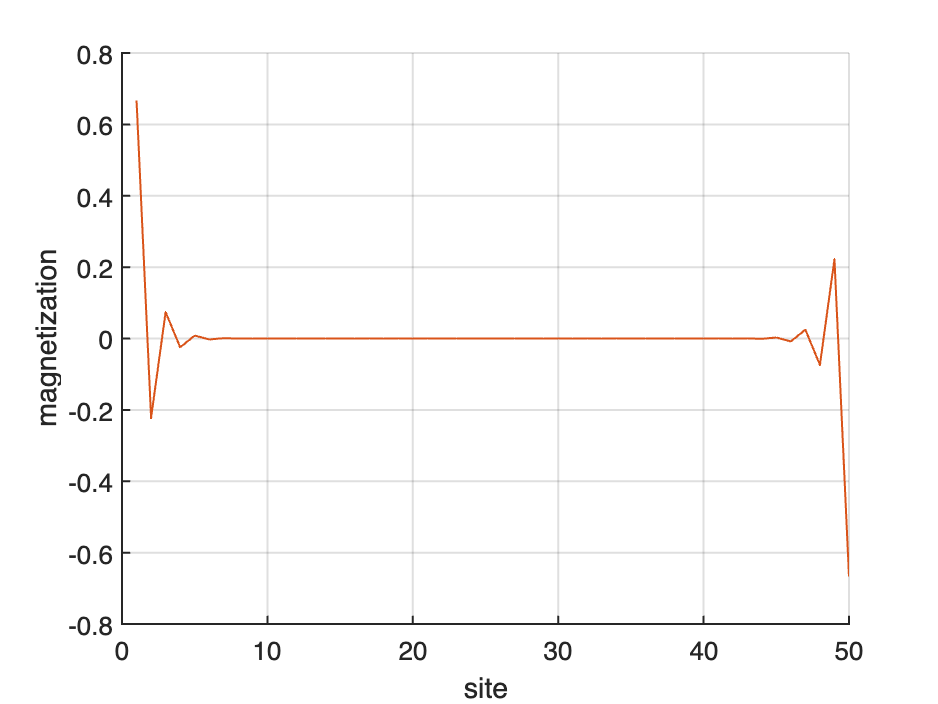

BC  = (1,1)

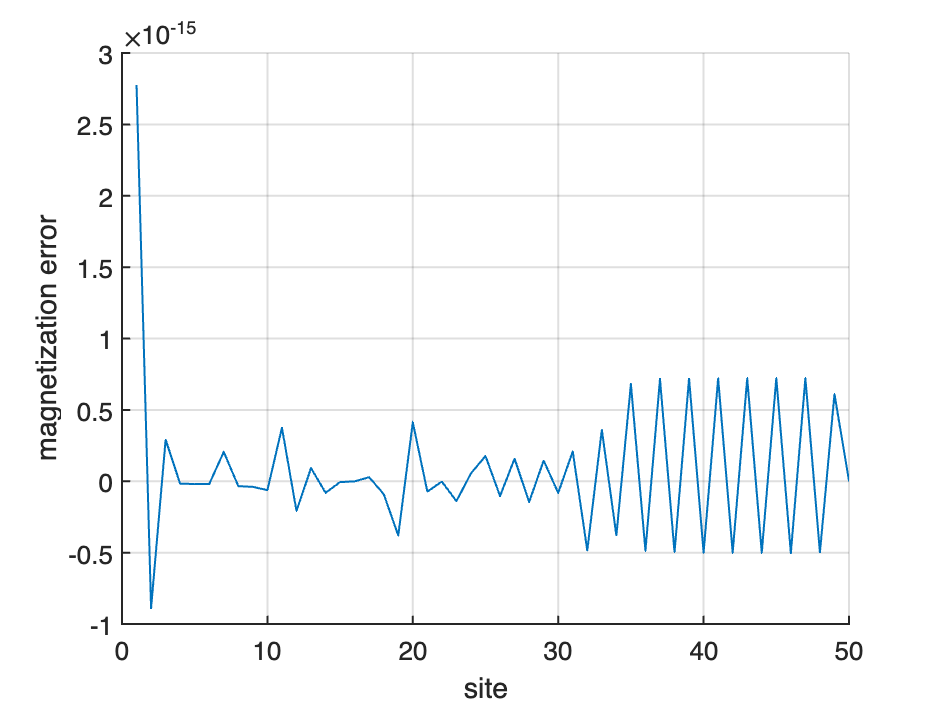

BC  = (1,1)

Norm of MPS = 0.7071


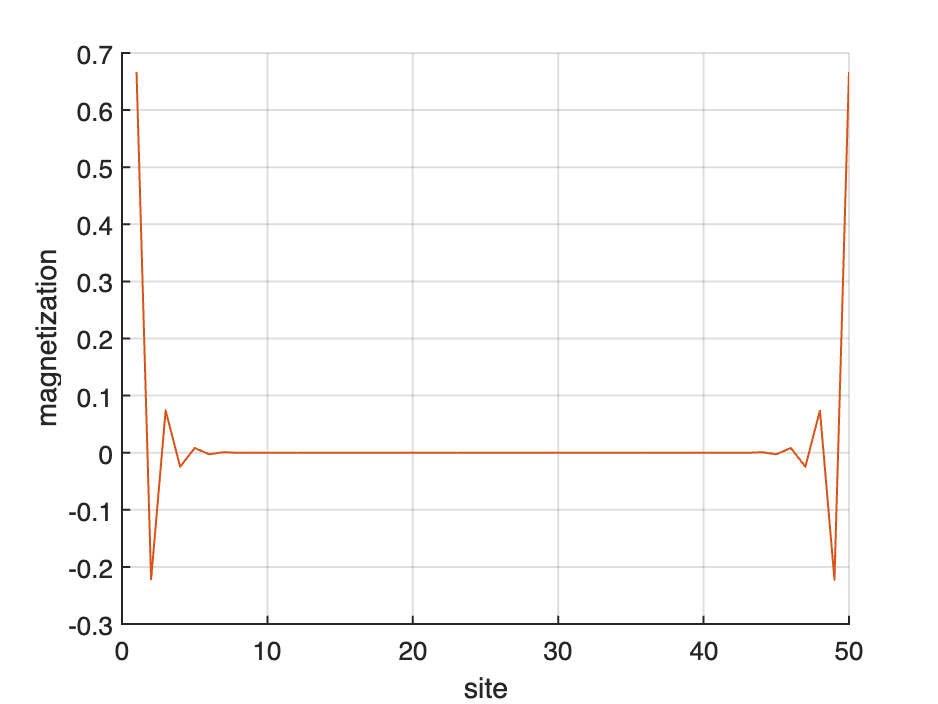

BC  = (1,2)

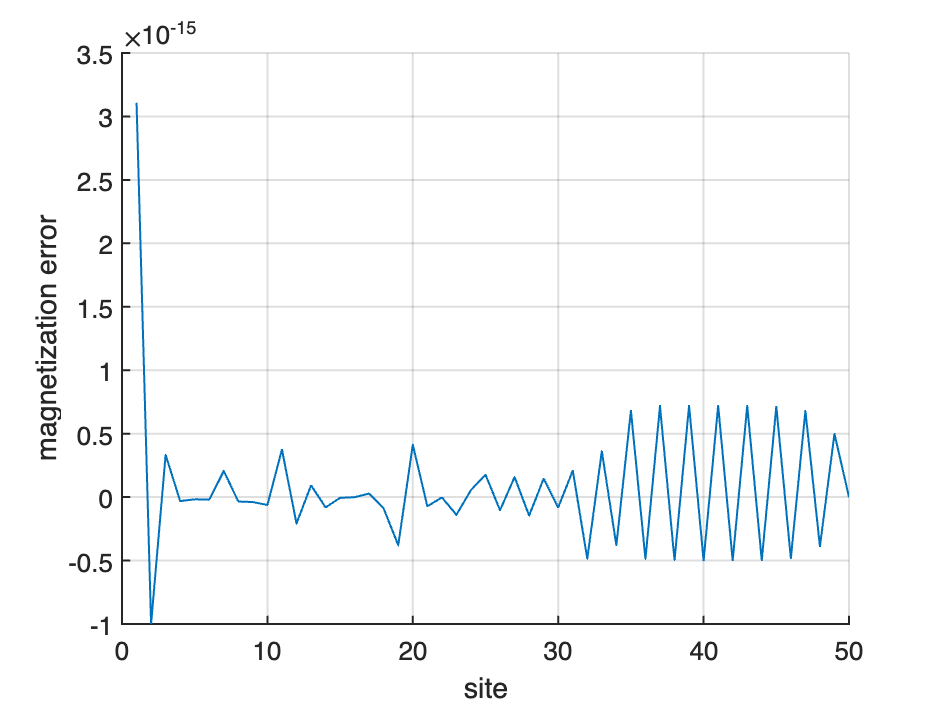

BC  = (1,2)

Norm of MPS = 0.7071


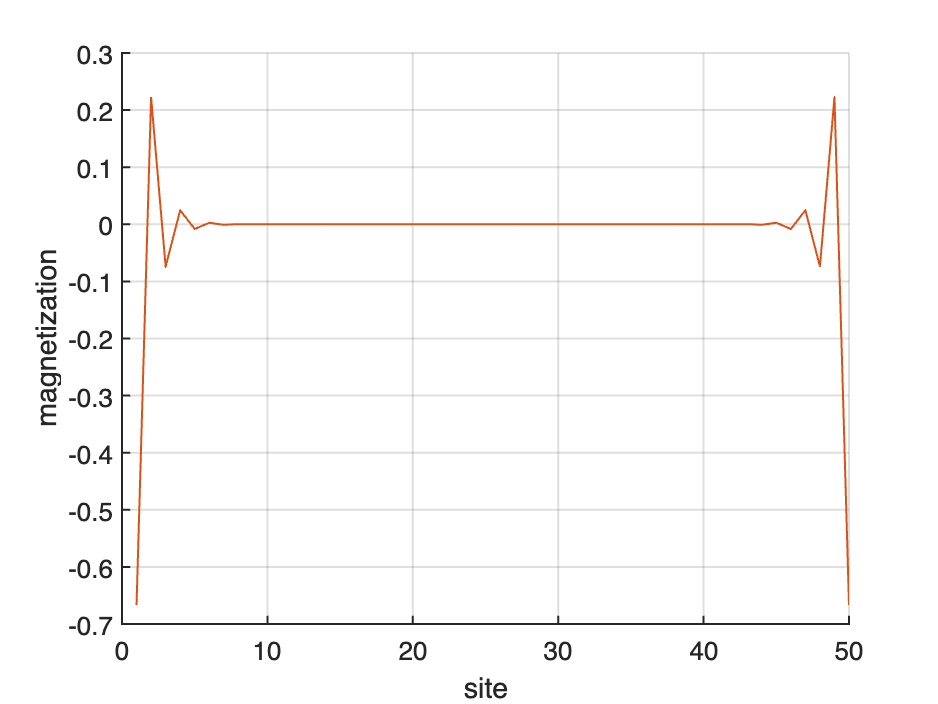

BC  = (2,1)

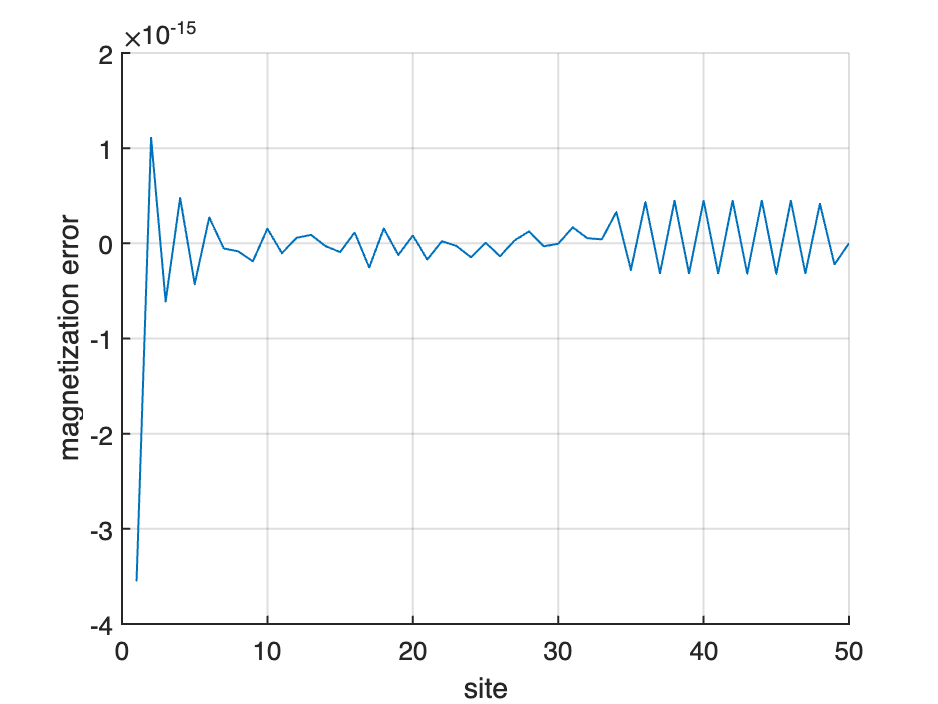

BC  = (2,1)

Norm of MPS = 0.7071


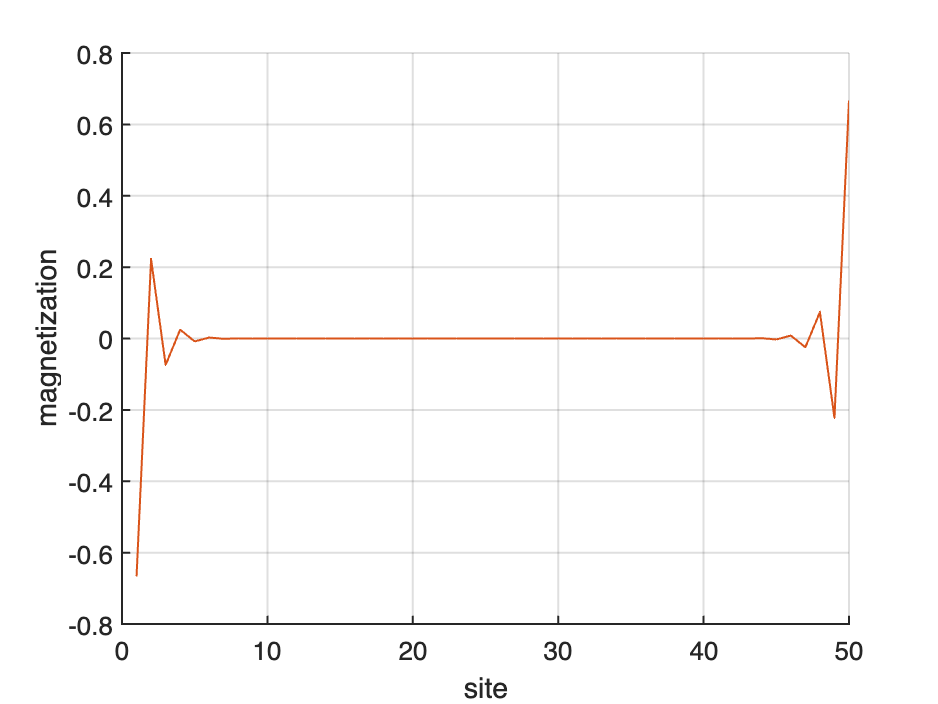

BC  = (2,2)

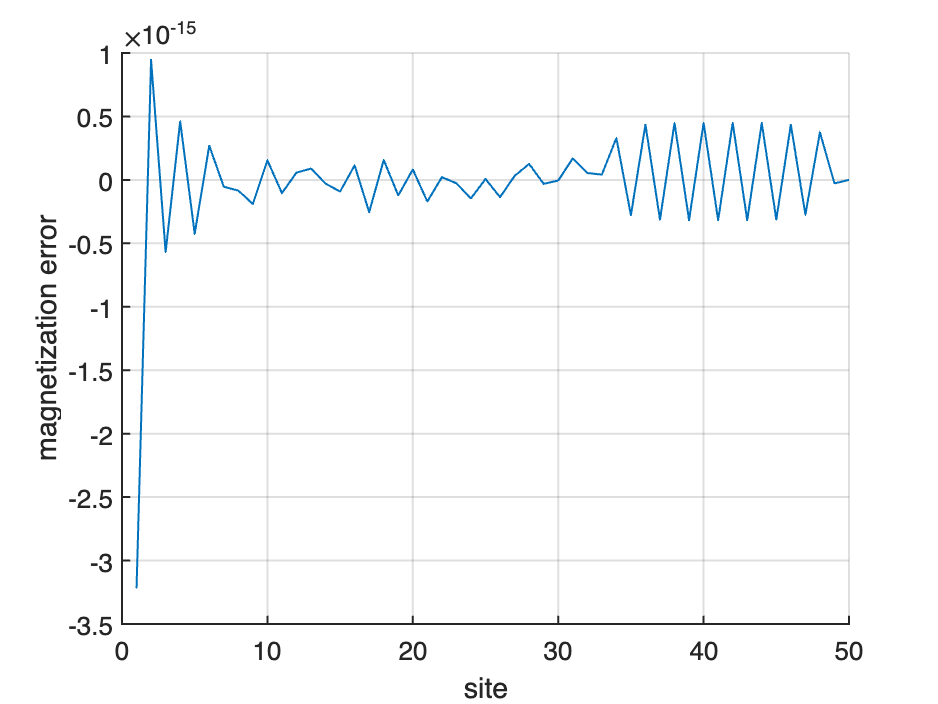

BC  = (2,2)


% Exercise a) Magnetization

% BC (alpha,beta)
for alpha = (1:2)
    for beta = (1:2)
        L = 50; % number of sites
        M = cell(1,L); % MPS
        M(:) = {AKLT};
        M{1} = M{1}(alpha,:,:);
        M{end} = M{end}(:,beta,:);

        % transform into left canonical form (normalized)
        [M,S] = canonForm(M,numel(M),[],0);
        fprintf('Norm of MPS = %.4g\n',S);

        % compute the magnetization
        mag = zeros(L,1);
        for itL = (1:L)
            % all left site contraction gives identity
%             if itL==1
%                 T = 1;
%             else
%                 T = eye(2,2);
%             end
%             T = updateLeft(T,2,M{itL},Sz,2,M{itL});
            T = updateLeft([],[],M{itL},Sz,2,M{itL});
            for itN = (itL+1:L)
                T = updateLeft(T,2,M{itN},[],[],M{itN});
            end
            mag(itL) = T;
        end

        n = (1:L);
        anal = (2*((-1)^alpha))*((-1/3).^n-((-1)^(alpha+beta)*(-1/3).^(L-n+1)))/(1+((-1)^(alpha+beta))*((-1/3)^L));
        anal = reshape(anal,[L,1]);
        Err = mag-anal;

        % compute error with analytic result



        figure;
        hold on;
        plot((1:L),anal,'LineWidth',1,'LineStyle','-');
        plot((1:L),mag,'LineWidth',1,'LineStyle','-');

        hold off;
        set(gca,'LineWidth',1,'FontSize',13);
        xlabel('site');
        ylabel('magnetization');
        grid on;
        fprintf('BC  = (%i,%i)',alpha,beta);
        %title('BC  = (%i,%i)',alpha,beta);

        figure;
        hold on;
        plot((1:L),Err,'LineWidth',1,'LineStyle','-');
        hold off;
        set(gca,'LineWidth',1,'FontSize',13);
        xlabel('site');
        ylabel('magnetization error');
        grid on;
        fprintf('BC  = (%i,%i)',alpha,beta);
        %title('BC  = (%i,%i)',alpha,beta);

    end
end

Norm of MPS = 0.7071


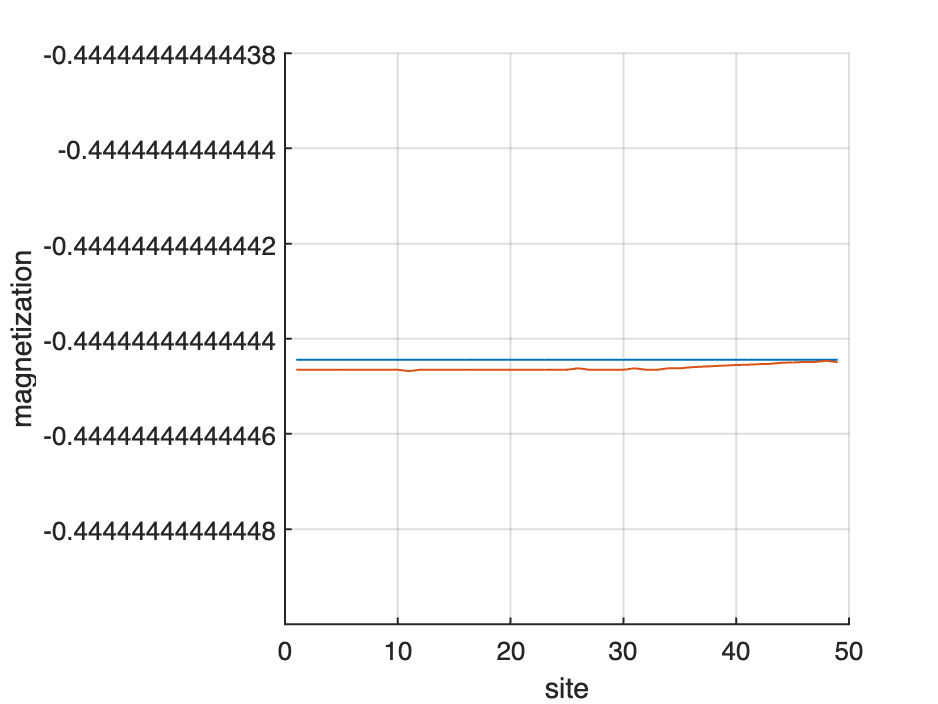

BC  = (1,1)

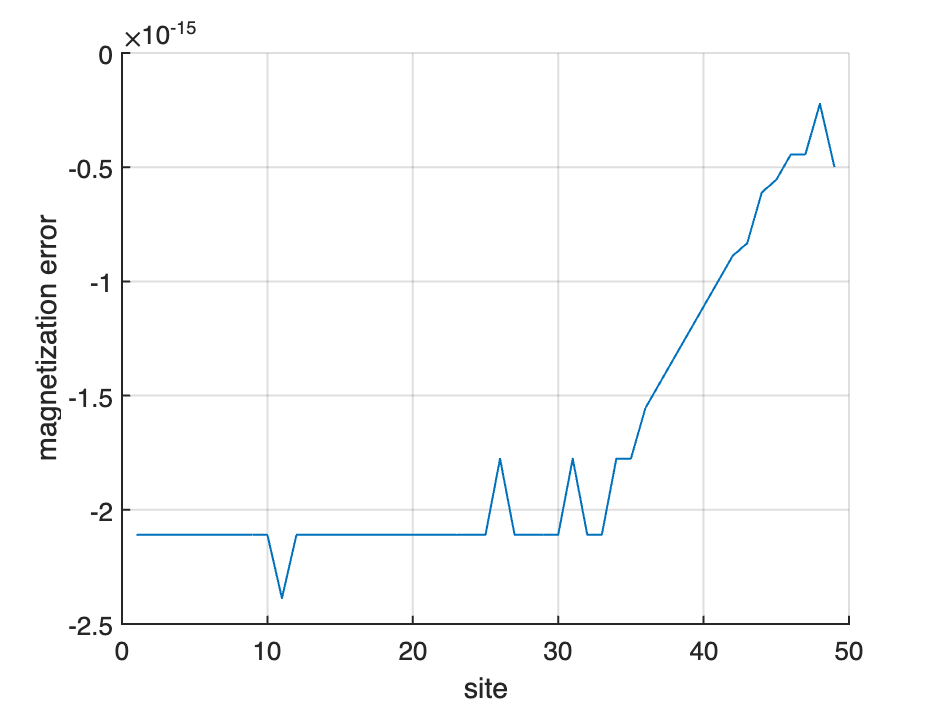

BC  = (1,1)

Norm of MPS = 0.7071


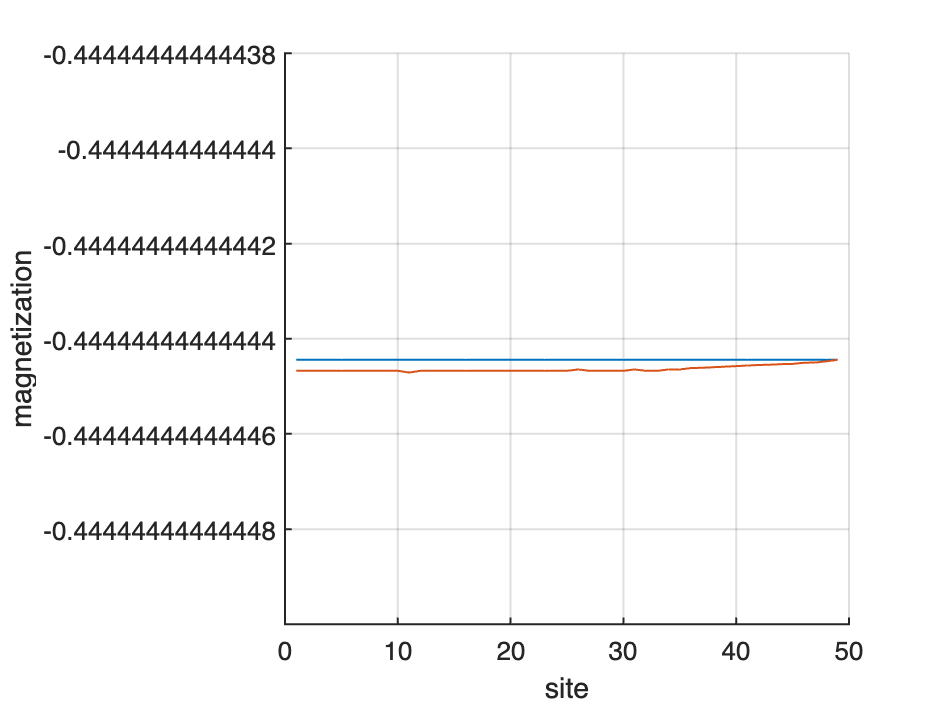

BC  = (1,2)

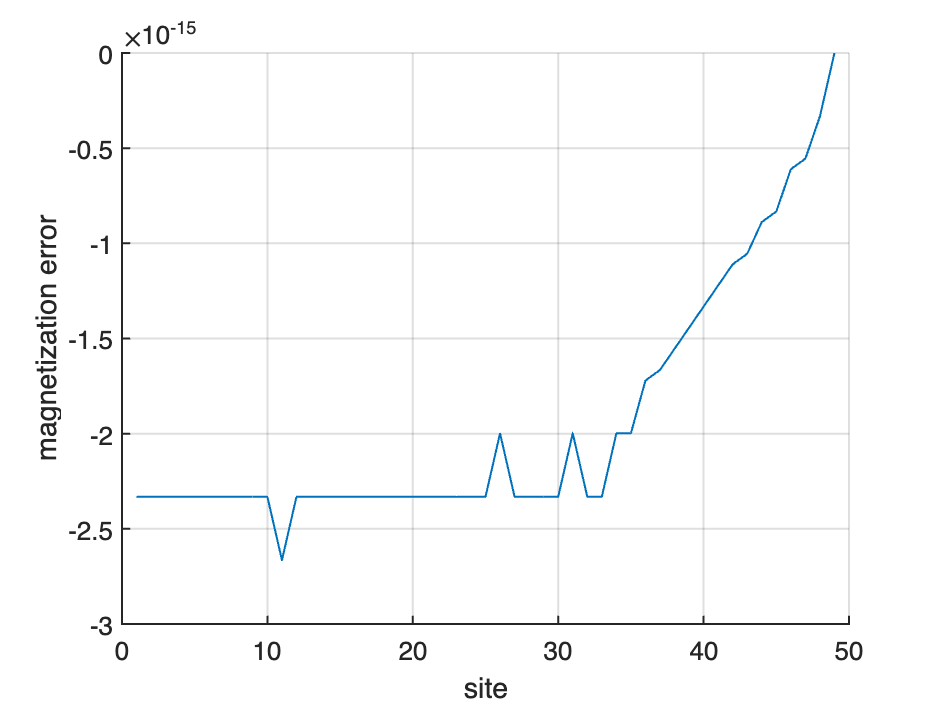

BC  = (1,2)

Norm of MPS = 0.7071


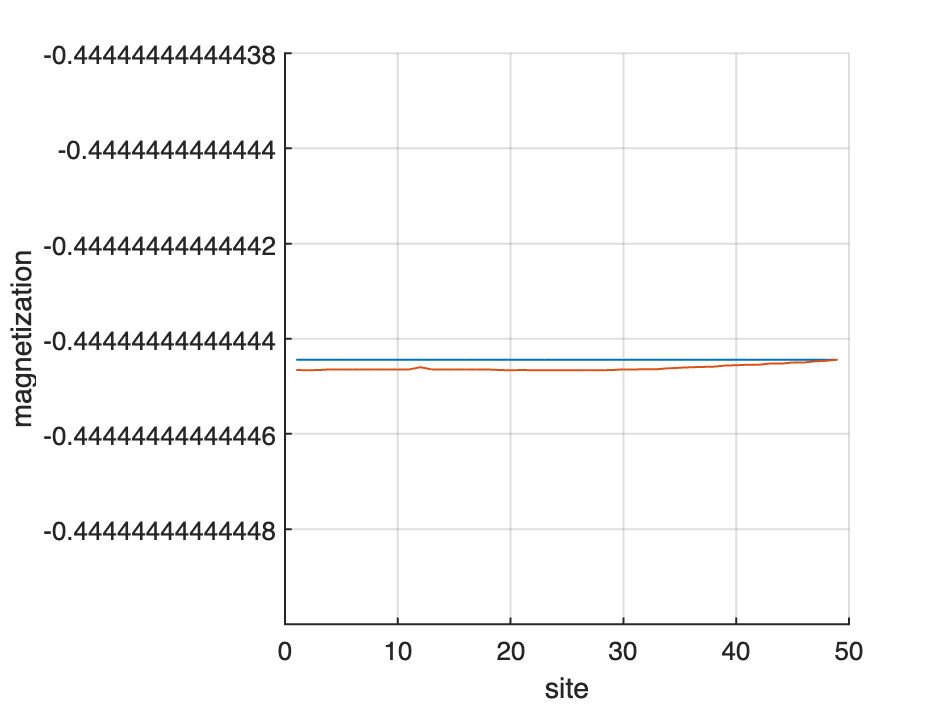

BC  = (2,1)

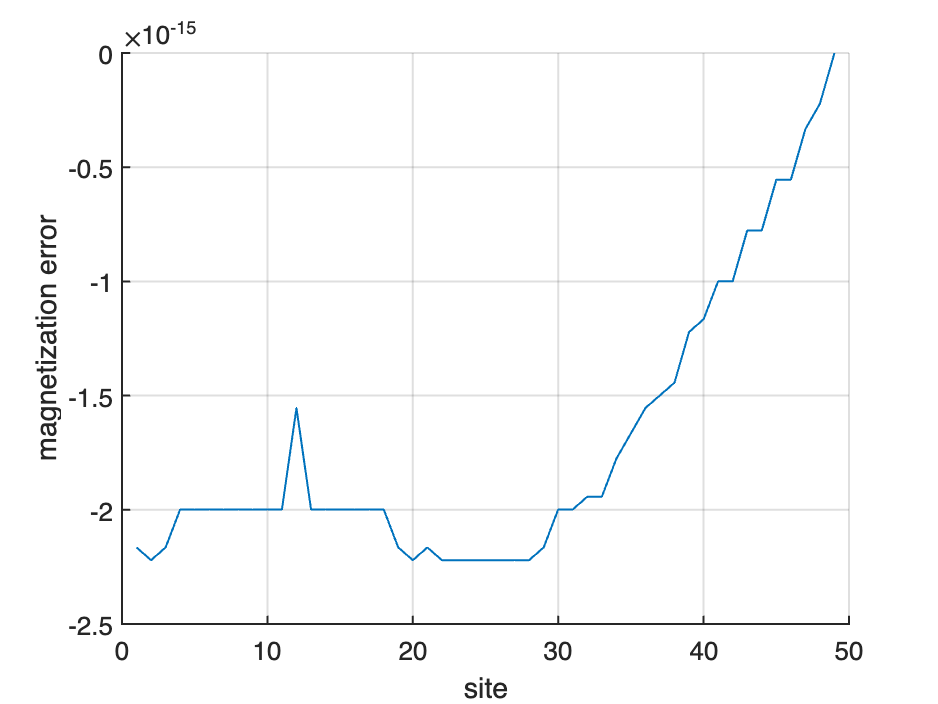

BC  = (2,1)

Norm of MPS = 0.7071


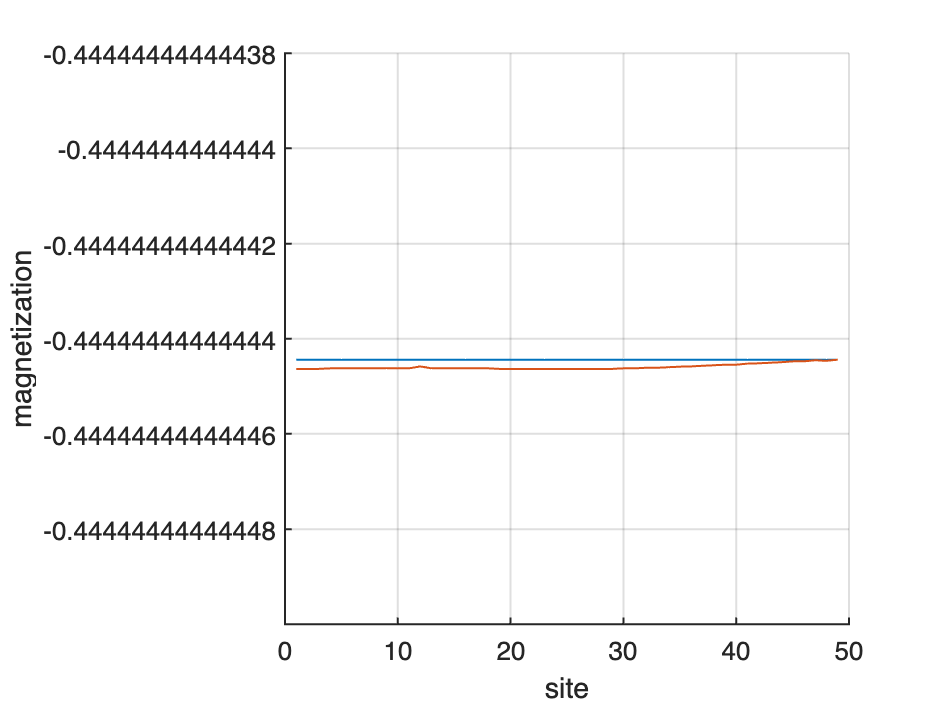

BC  = (2,2)

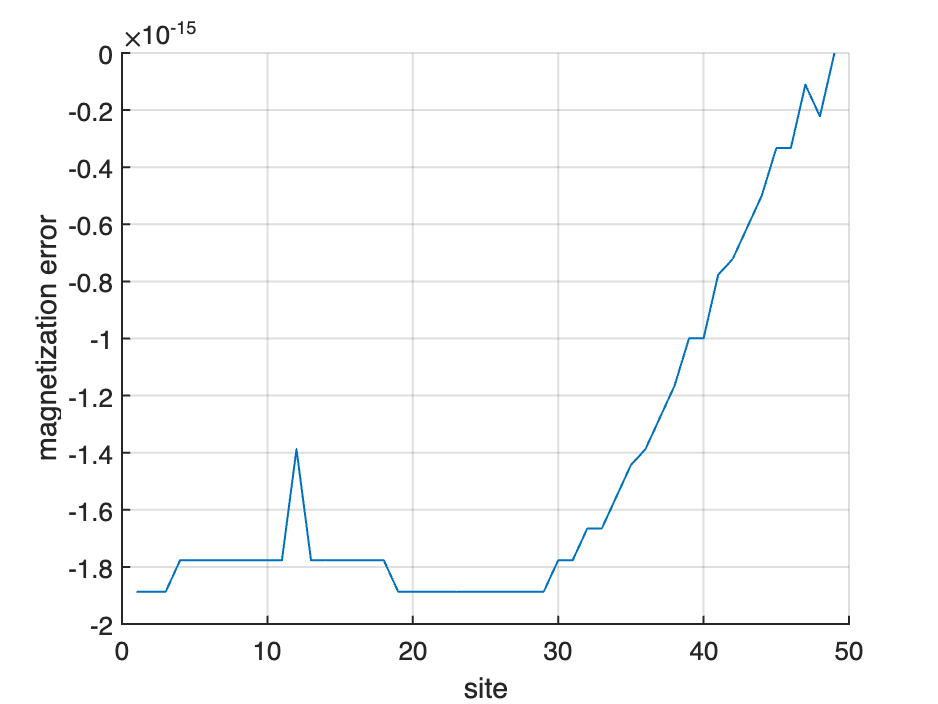

BC  = (2,2)

% exercise b) Correlation


% BC (alpha,beta)
for alpha = (1:2)
    for beta = (1:2)
        L = 50; % number of sites
        M = cell(1,L); % MPS
        M(:) = {AKLT};
        M{1} = M{1}(alpha,:,:);
        M{end} = M{end}(:,beta,:);

        % transform into left canonical form (normalized)
        [M,S] = canonForm(M,numel(M),[],0);
        fprintf('Norm of MPS = %.4g\n',S);

        % compute the correlation
        corr = zeros(L-1,1);
        for itL = (1:L-1)
            % all left site contraction gives identity
            if itL==1
                T = 1;
            else
                T = eye(2,2);
            end
            T = updateLeft(T,2,M{itL},Sz,2,M{itL});
            T = updateLeft(T,2,M{itL+1},Sz,2,M{itL+1});
            for itN = (itL+2:L)
                T = updateLeft(T,2,M{itN},[],[],M{itN});
            end
            corr(itL) = T;
        end

        anal = ((-4/9)-4*(-1)^(alpha+beta)*(-1/3)^L)/(1+(-1)^(alpha+beta)*(-1/3)^L)*ones(L-1,1);
        Err = corr-anal;

        % compute error with analytic result



        figure;
        hold on;
        plot((1:L-1),anal,'LineWidth',1,'LineStyle','-');
        plot((1:L-1),corr,'LineWidth',1,'LineStyle','-');

        hold off;
        set(gca,'LineWidth',1,'FontSize',13);
        xlabel('site');
        ylabel('magnetization');
        grid on;
        fprintf('BC  = (%i,%i)',alpha,beta);
        %title('BC  = (%i,%i)',alpha,beta);

        figure;
        hold on;
        plot((1:L-1),Err,'LineWidth',1,'LineStyle','-');
        hold off;
        set(gca,'LineWidth',1,'FontSize',13);
        xlabel('site');
        ylabel('magnetization error');
        grid on;
        fprintf('BC  = (%i,%i)',alpha,beta);
        %title('BC  = (%i,%i)',alpha,beta);

    end
end